% adding cross section to 3D scatter
% plotting only one dot per cell, the average pole age of the cell
%myfolder = '/MATLAB Drive/myfolder' ;   % new folder name 
%folder = mkdir([filepath,filesep,myfolder]) ;
%filepath  = [filepath,filesep,myfolder];
i_cells = 118;
i_cells =118;
file_path = sprintf('Cells/%d.txt',i_cells);
cells=importdata(file_path);

%x = [cells(:,4);cells(:,7)];
%y = [cells(:,5);cells(:,8)];
%z = [cells(:,6);cells(:,9)];
%c = [cells(:,27);cells(:,28)] %pole ages
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
c1 = cells(:,27); % p age
c2 = cells(:,28); % q age

c = (c1 + c2)/2; % sum of ages for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

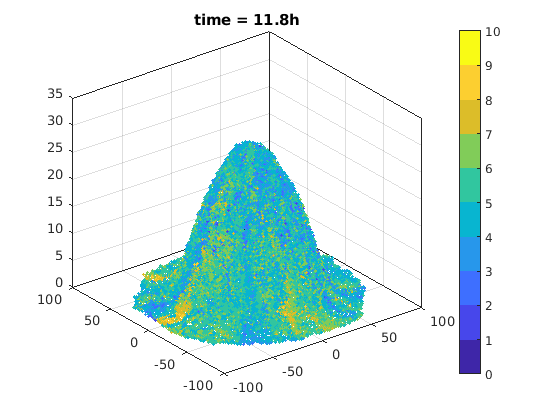


subplot(1,1,1)
scatter3(x,y,z,5,c, 'filled');
axis([-100 100 -100 100 0 35])
box on
h1=colorbar;
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h'])

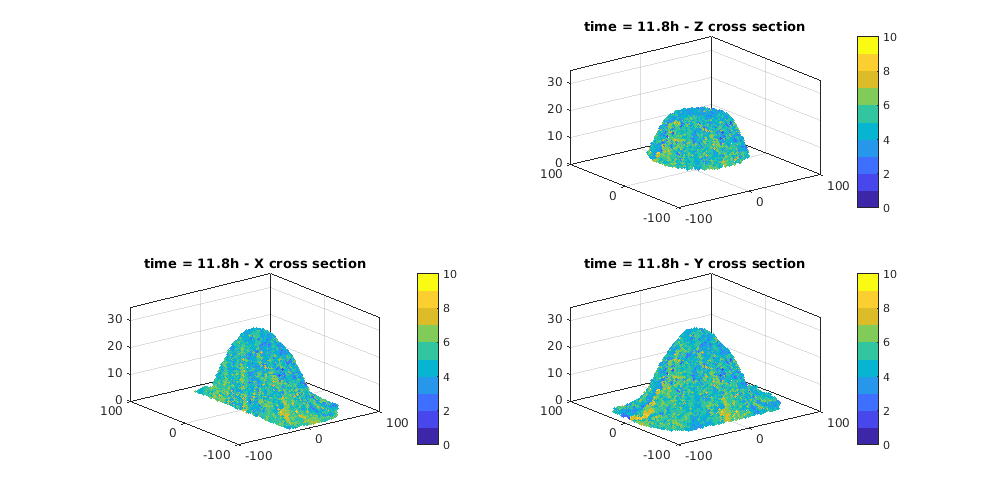



subplot(2,2,2)
z_min =6;
z_max =20;
indices_of_z = find((z<z_max & z>z_min));
scatter3(x(indices_of_z),y(indices_of_z),z(indices_of_z),5,c(indices_of_z), 'filled');
axis([-100 100 -100 100 0 35])
%view(0,90);
box on
h1=colorbar;
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h - Z cross section'])

subplot(2,2,3)
x_min =-21;
x_max =75;
indices_of_x = find((x<x_max & x>x_min));
scatter3(x(indices_of_x),y(indices_of_x),z(indices_of_x),5,c(indices_of_x), 'filled');
axis([-100 100 -100 100 0 35])
%view(90,0);
box on
h1=colorbar;
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h - X cross section'])

subplot(2,2,4)

y_min =-68;
y_max =47;
indices_of_y = find((y<y_max & y>y_min));
scatter3(x(indices_of_y),y(indices_of_y),z(indices_of_y),5,c(indices_of_y), 'filled');
axis([-100 100 -100 100 0 35])
%view(90,0);
box on
h1=colorbar;
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h - Y cross section'])

% enforces size of plot
set(gcf,'position',[0,0,1000,500]);

% quiver3
subplot(1,1,1)
% You can find out the indices of the cells whose center of mass has height less than 2um by the following command:
% https://stackoverflow.com/questions/29632430/quiver3-arrow-color-corresponding-to-magnitude
% You can plot all such cells with stick representation and different color by the following command:
q = quiver3(cells(:,4), cells(:,5), cells(:,6), cells(:,7)-cells(:,4), cells(:,8)-cells(:,5), cells(:,9)-cells(:,6));
%view(90,0);
%quiver3(cells(i_btm(i2),4), cells(i_btm(i2),5), cells(i_btm(i2),6), cells(i_btm(i2),7)-cells(i_btm(i2),4), cells(i_btm(i2),8)-cells(i_btm(i2),5), cells(i_btm(i2),9)-cells(i_btm(i2),6), 'r', 'ShowArrowHead','off', 'Autoscale','off');
% You can adjust the view angles of the plot by:

%// Compute the magnitude of the vectors
mags = sqrt(sum(cat(2, q.UData(:), q.VData(:), ...
            reshape(q.WData, numel(q.UData), [])).^2, 2));
min(mags)

ans = 0.8785

max(mags)

ans = 3.0072

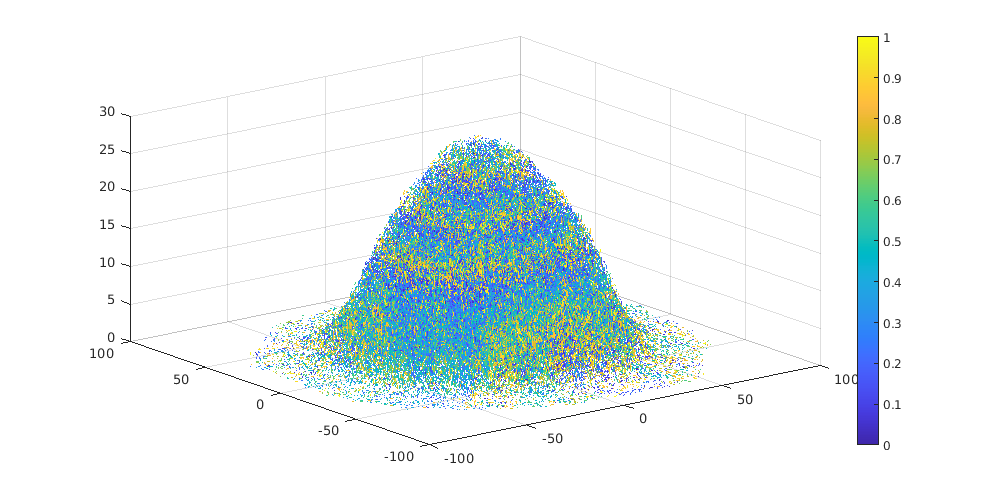


%// Get the current colormap
currentColormap = colormap(gca);
%colormap default
%caxis([floor(min(mags)) ceil(max(mags))])

%// Now determine the color to make each arrow using a colormap
[~, ~, ind] = histcounts(mags, size(currentColormap, 1));

%// Now map this to a colormap to get RGB
cmap = uint8(ind2rgb(ind(:), currentColormap) * 255);
cmap(:,:,4) = 255;
cmap = permute(repmat(cmap, [1 3 1]), [2 1 3]);

%// We repeat each color 3 times (using 1:3 below) because each arrow has 3 vertices
set(q.Head, ...
    'ColorBinding', 'interpolated', ...
    'ColorData', reshape(cmap(1:3,:,:), [], 4).');   %'

%// We repeat each color 2 times (using 1:2 below) because each tail has 2 vertices
set(q.Tail, ...
    'ColorBinding', 'interpolated', ...
    'ColorData', reshape(cmap(1:2,:,:), [], 4).');
colorbar